mydata = load('RSdata.mat')

mydata = struct with fields:
                   rt_tout: [1600×1 double]
           rt_motor_speeds: [1×1 struct]
           rt_optical_flow: [1×1 struct]
    rt_initial_sensor_data: [1×1 struct]
                    rt_a_x: [1×1 struct]
                    rt_a_y: [1×1 struct]
                    rt_a_z: [1×1 struct]
                      rt_p: [1×1 struct]
                      rt_q: [1×1 struct]
                      rt_r: [1×1 struct]
               rt_pressure: [1×1 struct]
           rt_z_ultrasonic: [1×1 struct]



ms = mydata.rt_motor_speeds.signals.values;

u = mydata.rt_optical_flow.signals.values(:,1);
v = mydata.rt_optical_flow.signals.values(:,2);
a_x = mydata.rt_a_x.signals.values;
a_y = mydata.rt_a_y.signals.values;
a_z = mydata.rt_a_z.signals.values;
p = mydata.rt_p.signals.values;
q = mydata.rt_q.signals.values;
r = mydata.rt_r.signals.values;
p_0 = mydata.rt_pressure.signals.values;
z_us = mydata.rt_z_ultrasonic.signals.values;

all_data = [u, v, a_x, a_y, a_z, p, q, r, p_0, z_us];
labels = ["u", "v", "a_x", "a_y", "a_z", "p", "q", "r", "p_0","z_us"];

u_mean = mean(u)

u_mean = single
0.0180

u_cov = cov(u)

u_cov = single
0.0140

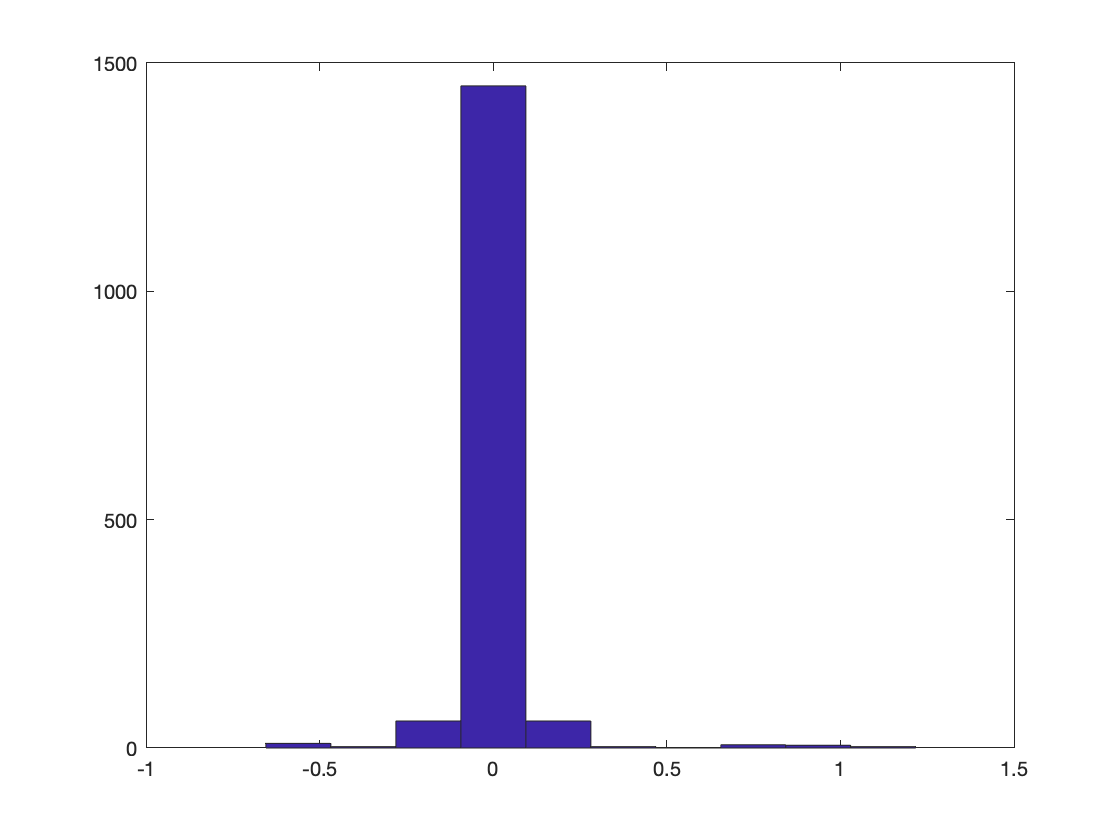

hist(u,10)


v_mean = mean(v)

v_mean = single
-0.0048

v_cov = cov(v)

v_cov = single
0.0126

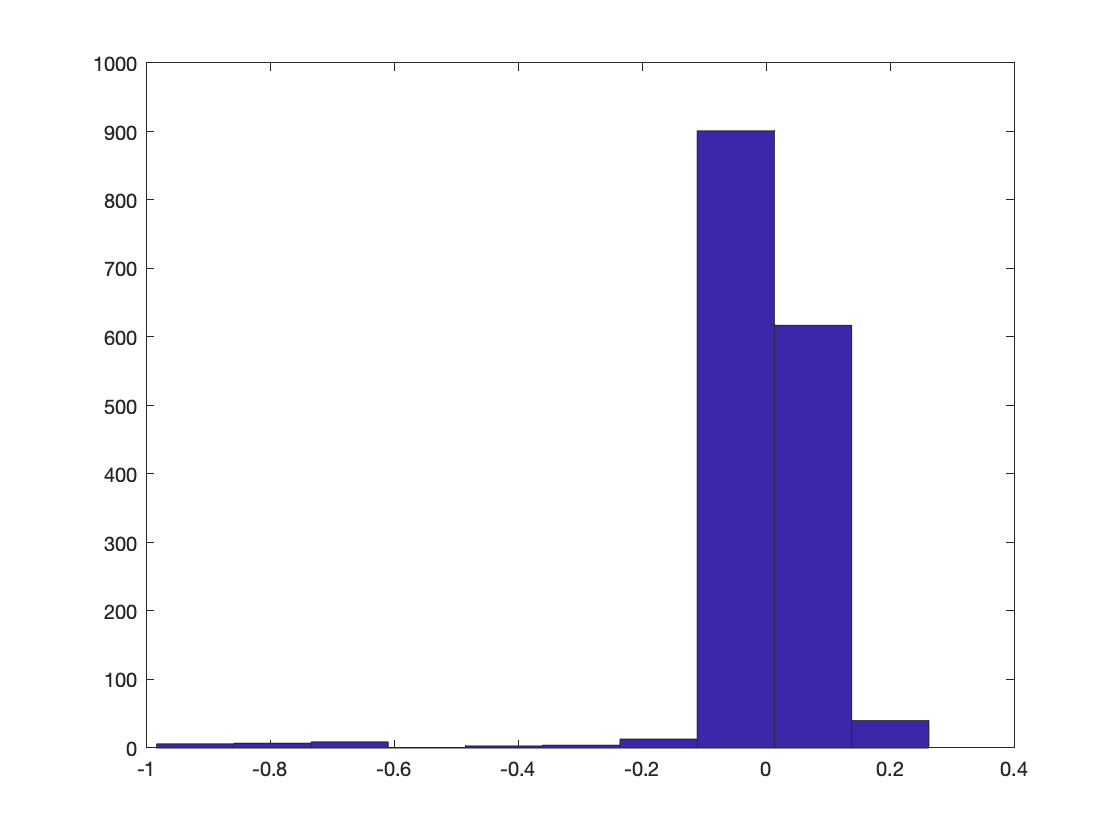

hist(v,10)


a_x_mean = mean(a_x)

a_x_mean = single
-0.0272

a_x_cov = cov(a_x)

a_x_cov = single
0.3136

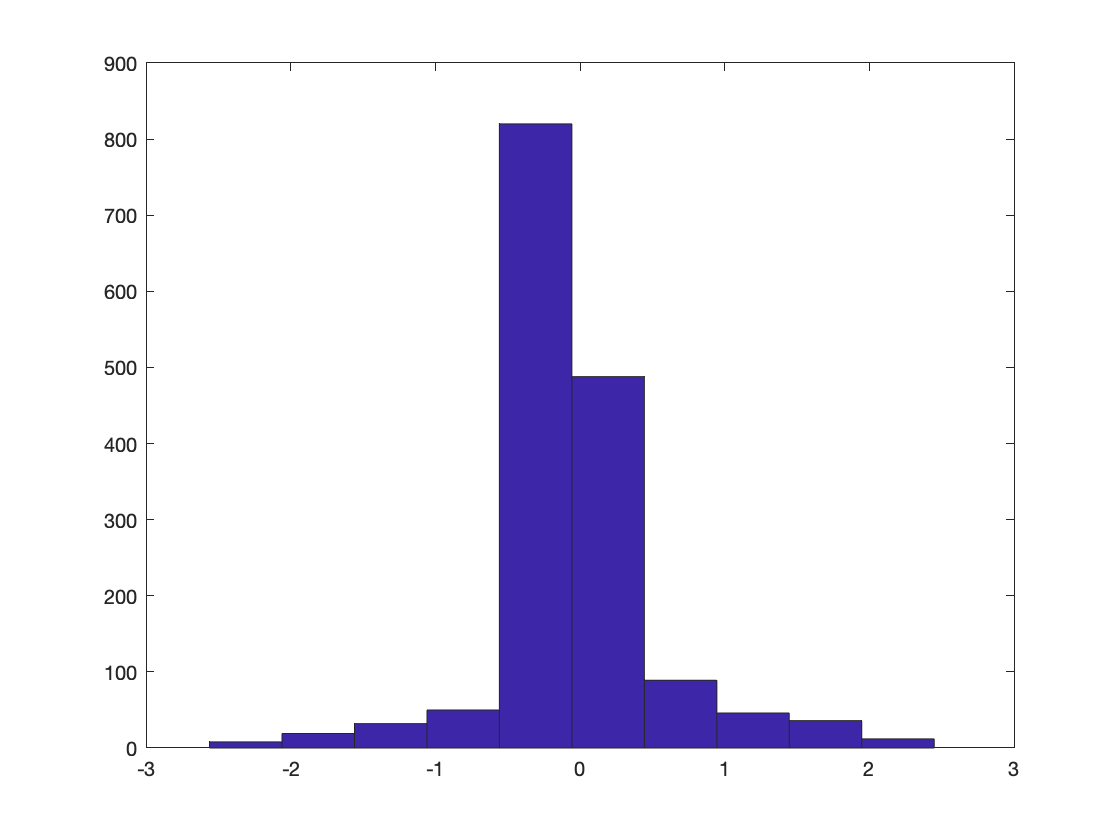

hist(a_x,10)


a_z_mean = mean(a_y)

a_z_mean = single
-0.0107

a_z_cov = cov(a_y)

a_z_cov = single
0.1038

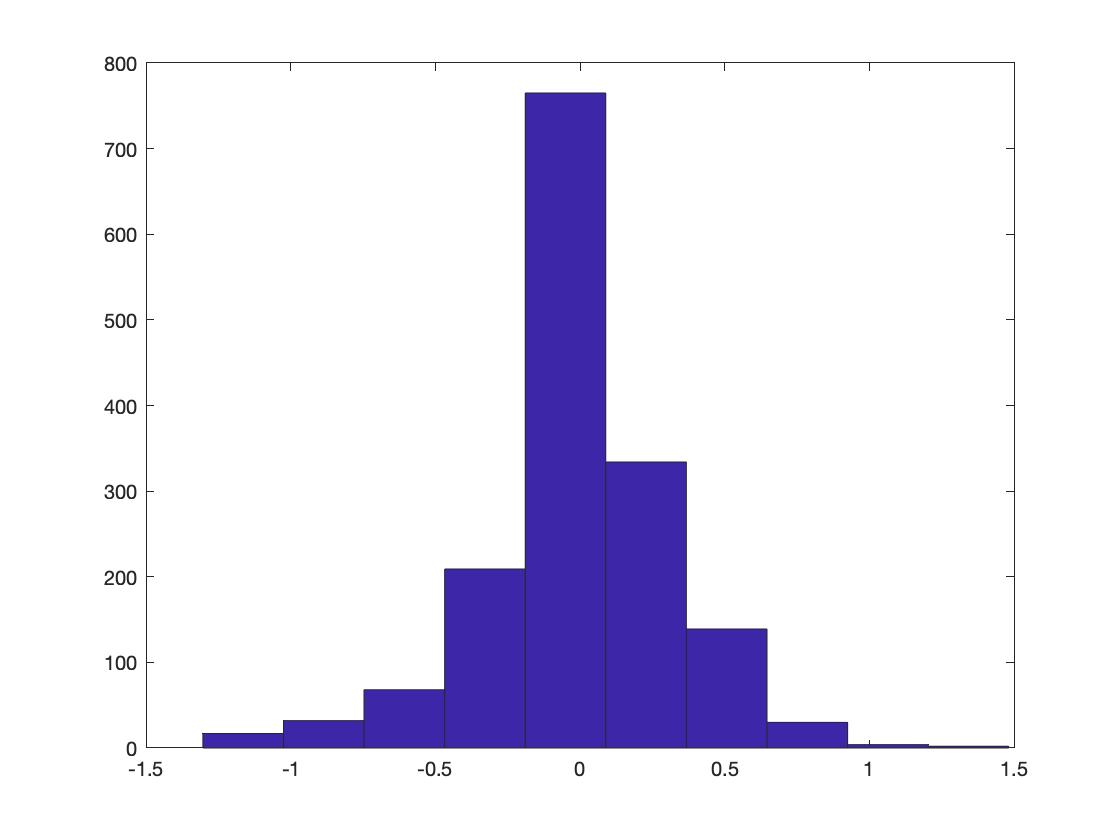

hist(a_y)


a_z_mean = mean(a_z)

a_z_mean = single
-8.7470

a_z_cov = cov(a_z)

a_z_cov = single
0.0989

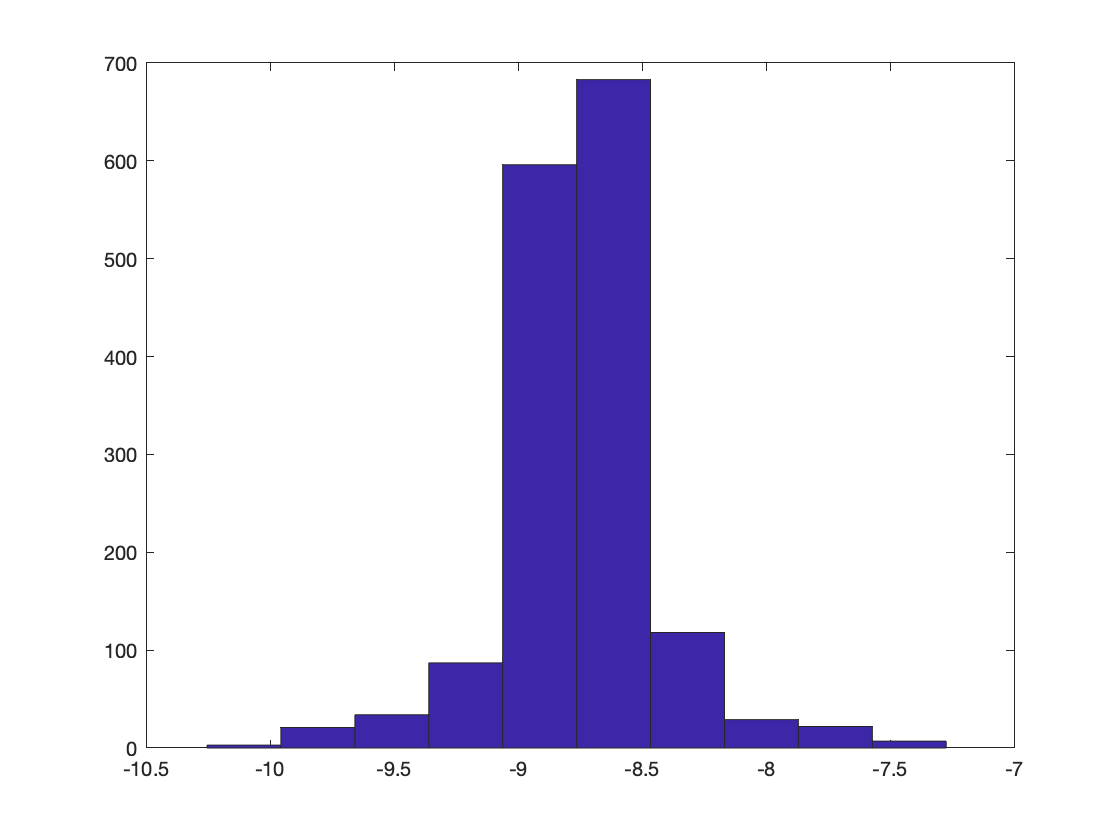

hist(a_z)


p_mean = mean(p)

p_mean = single
-0.0578

p_cov = cov(p)

p_cov = single
0.0132

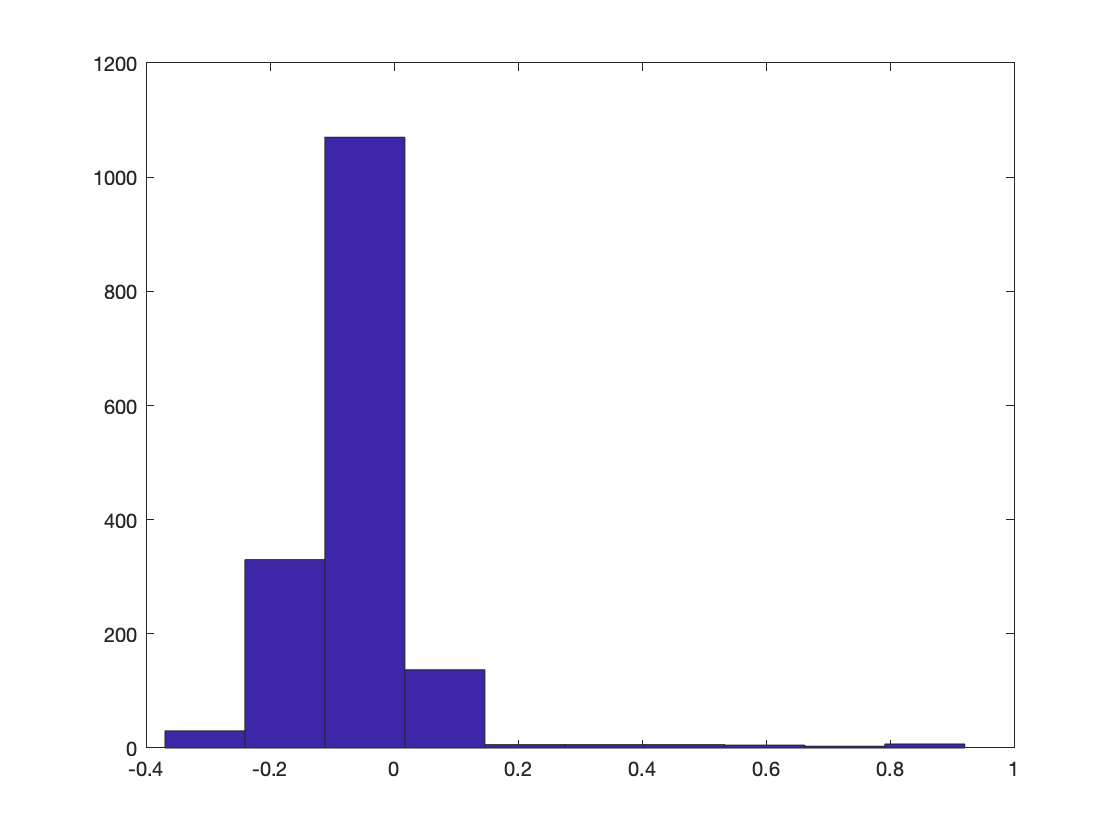

hist(p)


q_mean = mean(q)

q_mean = single
-0.0313

q_cov = cov(q)

q_cov = single
0.0159

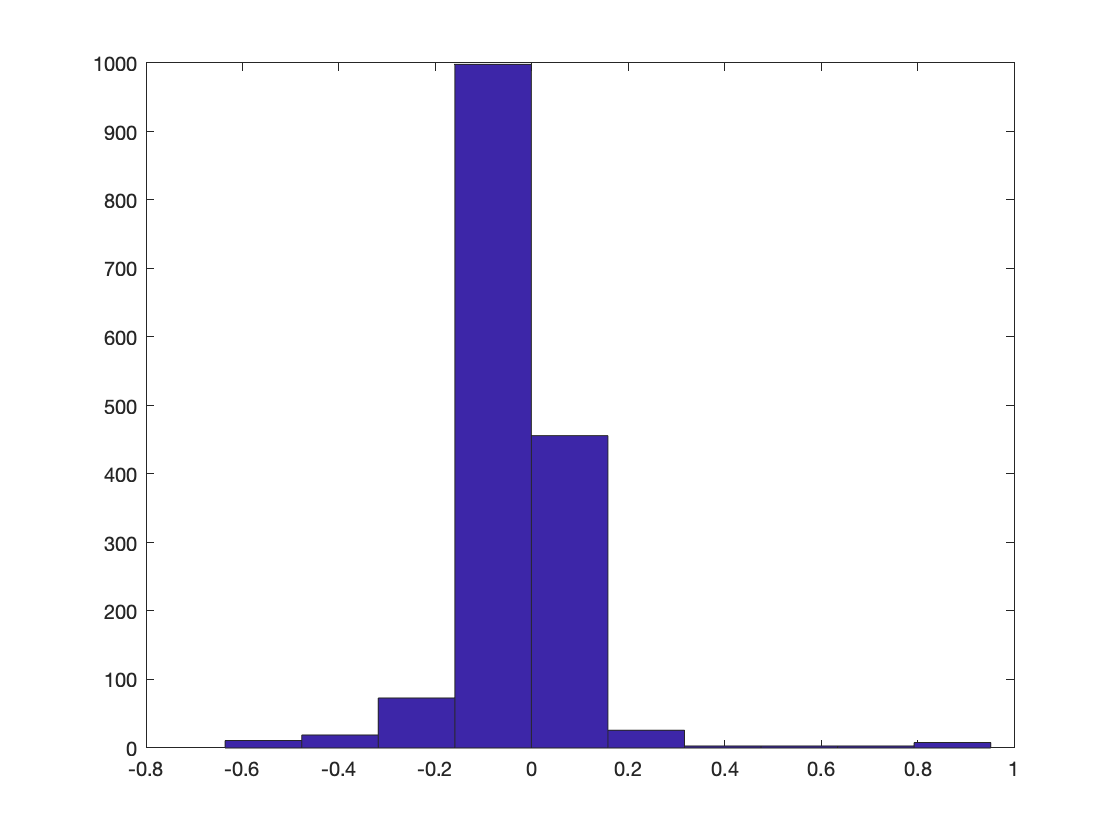

hist(q)


r_mean = mean(r)

r_mean = single
0.0064

r_cov = cov(r)

r_cov = single
0.0033

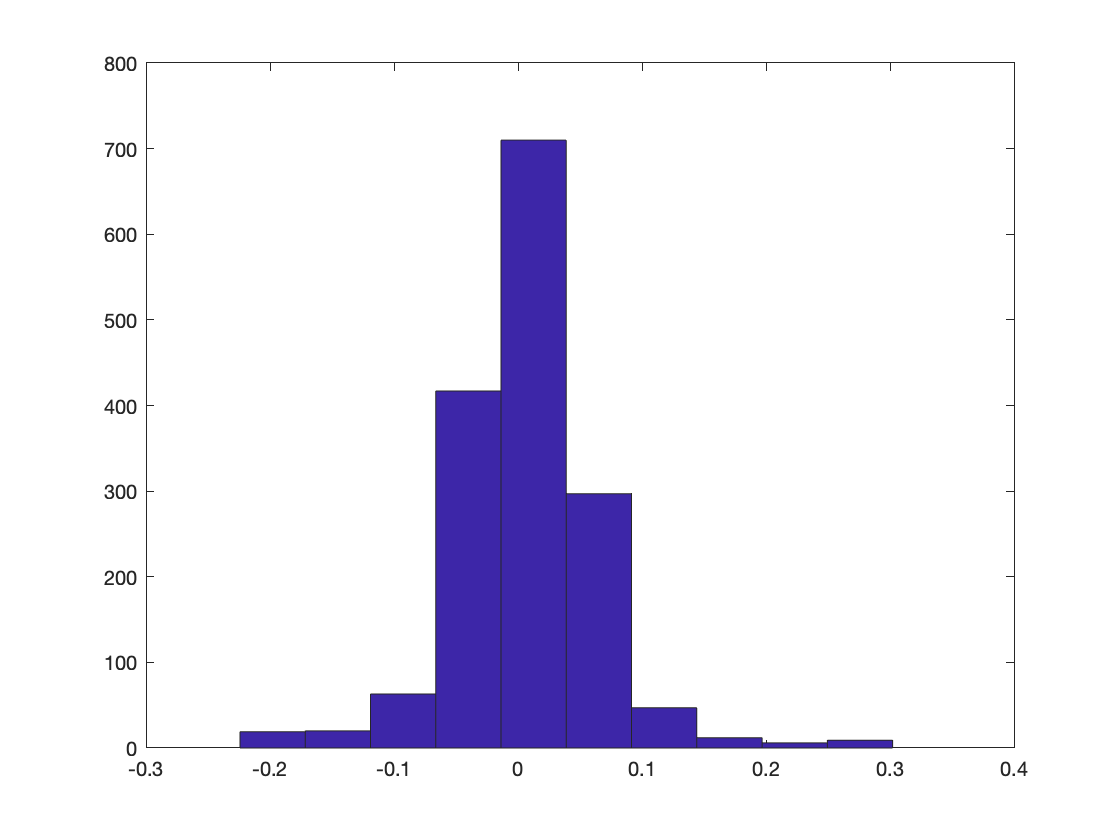

hist(r)


g = 9.8; % acceleration due to gravity m/s^2
M = 0.0289644; % molar mass of air in kg/mol
R = 8.31432; % universal gas constant Nm/mol/k
p0 = 101325 % Pa standard pressure

p0 = 101325


T =288.15;  % Assumed temperature in kelvin
K =-g*M/R/T;
z_hypsometric =@(P) 1/K.*log(P./p0)

z_hypsometric = function_handle with value:
    @(P)1/K.*log(P./p0)


p_0_mean = mean(p_0)

p_0_mean = single
1.0012e+05

difference = z_hypsometric(p_0) - z_hypsometric(p_0_mean)

difference = 1600×1 single column vector
   -0.1258
   -0.1258
   -0.1258
    0.1359
    0.1359
   -0.0102
   -0.0102
   -0.0102
    0.1426
    0.1426


p_cov = cov(difference) %p_0

p_cov = single
0.0226

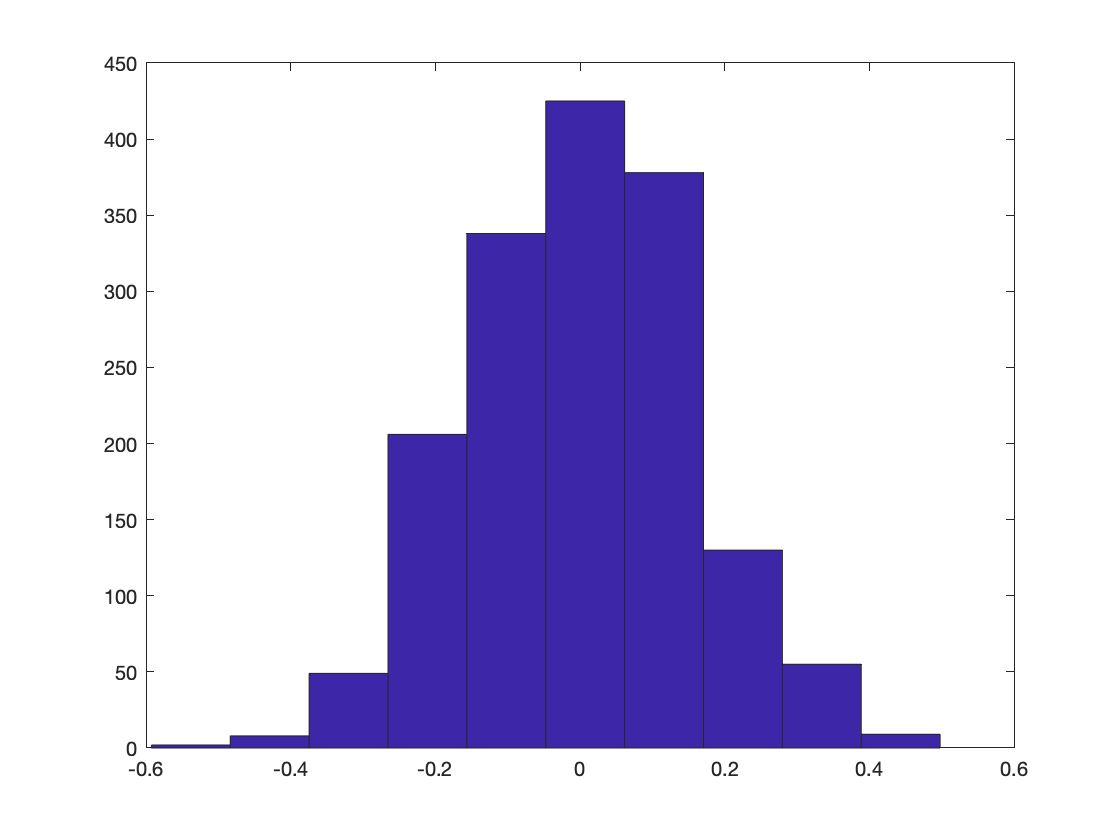

hist(difference)



z_us_mean = mean(z_us)

z_us_mean = single
0.6146

z_us_cov = cov(z_us)

z_us_cov = single
9.4200e-05

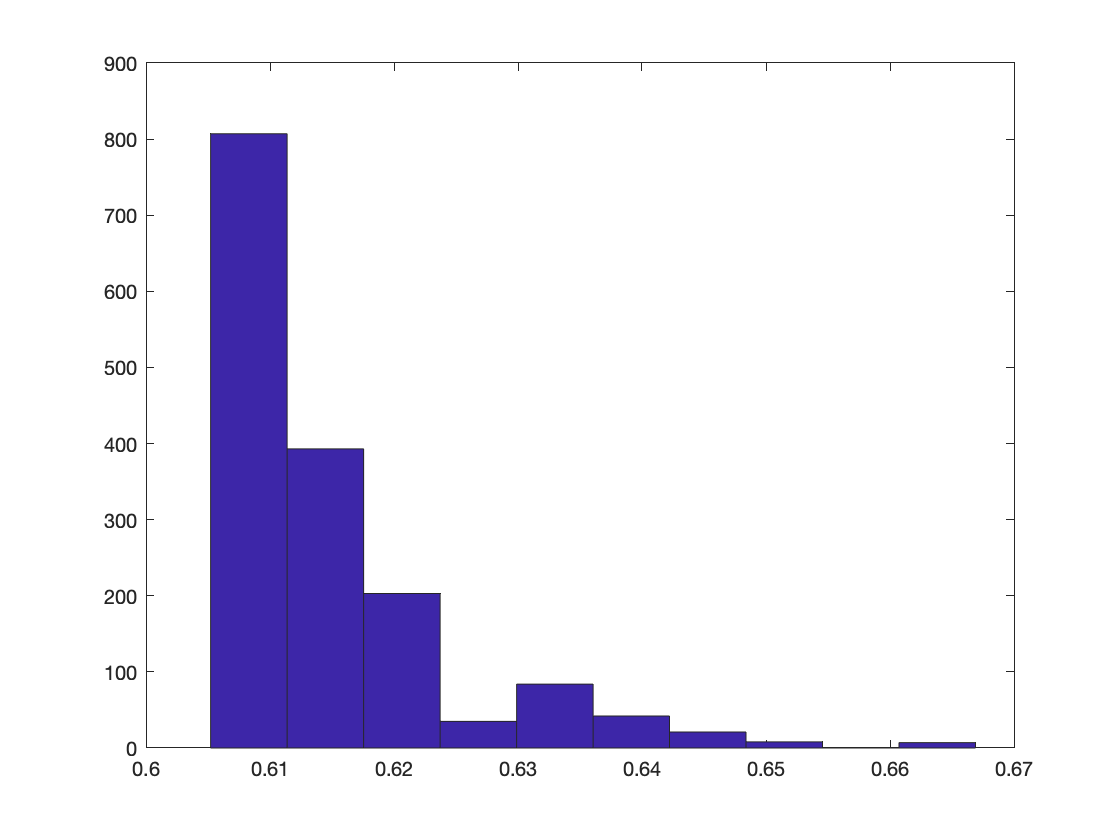

hist(z_us)


for i = 1:10
    for j = 1:10
        correlation = corr(all_data(:,i),all_data(:,j));
        if correlation > 0.3 && (i ~= j)
            fprintf('Correlation between %s and %s is %f \n',labels(i),labels(j),corr(all_data(:,i),all_data(:,j)))
        end
    end
end

Correlation between u and v is 0.378120 
Correlation between u and q is 0.556542 
Correlation between v and u is 0.378120 
Correlation between v and q is 0.382483 
Correlation between a_x and a_z is 0.617565 
Correlation between a_z and a_x is 0.617565 
Correlation between q and u is 0.556542 
Correlation between q and v is 0.382483 


corr_matrix = corrcoef(all_data)

corr_matrix = 10×10 single matrix
    1.0000    0.3781    0.0408    0.2385    0.2109   -0.1311    0.5565   -0.0882    0.0133    0.0583
    0.3781    1.0000   -0.1328    0.1368    0.0612   -0.6218    0.3825   -0.2735   -0.0434   -0.0904
    0.0408   -0.1328    1.0000   -0.1450    0.6176    0.1221   -0.0469    0.0258   -0.0006    0.2403
    0.2385    0.1368   -0.1450    1.0000    0.1760   -0.0275    0.2186   -0.0389   -0.0258    0.0167
    0.2109    0.0612    0.6176    0.1760    1.0000   -0.0068    0.0656   -0.1241    0.0560    0.0102
   -0.1311   -0.6218    0.1221   -0.0275   -0.0068    1.0000   -0.3152    0.0739    0.0046    0.0889
    0.5565    0.3825   -0.0469    0.2186    0.0656   -0.3152    1.0000    0.1160    0.0172    0.0106
   -0.0882   -0.2735    0.0258   -0.0389   -0.1241    0.0739    0.1160    1.0000   -0.0463   -0.0819
    0.0133   -0.0434   -0.0006   -0.0258    0.0560    0.0046    0.0172   -0.0463    1.0000   -0.0466
    0.0583   -0.0904    0.2403    0.0167    0.0102    0.0

A = [0 1;
     0 0];
T = 1/200;
syms t
exp(A.*t)

$$ans = \left(\begin{array}{cc} 1 & {\mathrm{e}}^{t}\\ 1 & 1 \end{array}\right)$$


discrete_system = ss(A_throttle,B_throttle,[1 0],0,1/200)

Unrecognized function or variable 'A_throttle'.

syms a_x a_y a_z h 
theta_estimate = atan(-a_x/sqrt(a_y^2 + a_z^2)) 

$$theta\_estimate = -\mathrm{atan}\left(\frac{a_{x}}{\sqrt{{a_{y}}^{2}+{a_{z}}^{2}}}\right)$$

phi_estimate = atan(a_y/a_z)

$$phi\_estimate = \mathrm{atan}\left(\frac{a_{y}}{a_{z}}\right)$$

K_fudge = 100;
OF_est = K_fudge*h *[u;v];
u_est = OF_est(1)

$$u\_est = \frac{150761375\,h}{134217728}$$

v_est = OF_est(2)

$$v\_est = \frac{150761375\,h}{134217728}$$